# Testing the trained network

Loading NN and setting image size

load('nn2.mat');     % I want to load vzpre1 as vz.
im_size = [360, 480];

Loading NN and setting image size

I = imread('test.jpg');
I = imresize(I, im_size);


Get the results from NN 

C = semanticseg(I,net);
B = labeloverlay(I,C);

Overlay the results from NN on image

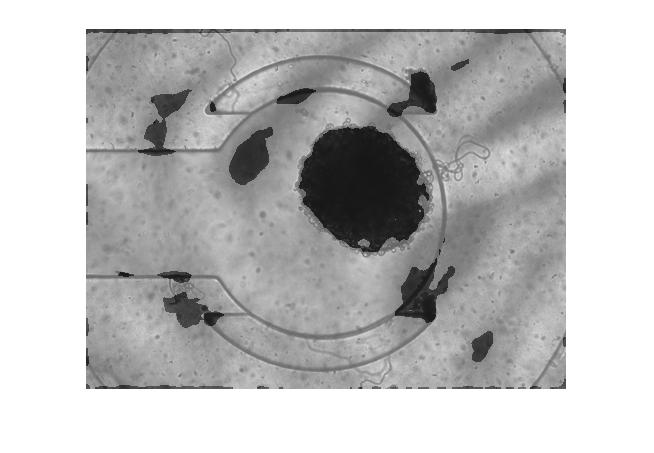

figure
label_overlay = labeloverlay(I,C);
label_overlay = rgb2gray(label_overlay);
imshow(label_overlay)

Binarize the resultant image

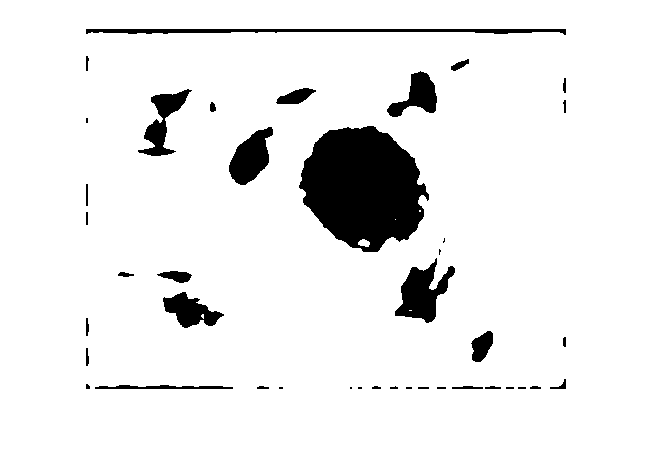

figure
white = zeros(im_size);
tissue_pot = labeloverlay(white,C);
tissue_pot = rgb2gray(tissue_pot);
tissue_pot_binary = imbinarize(tissue_pot, 0.1);
imshow(tissue_pot_binary)

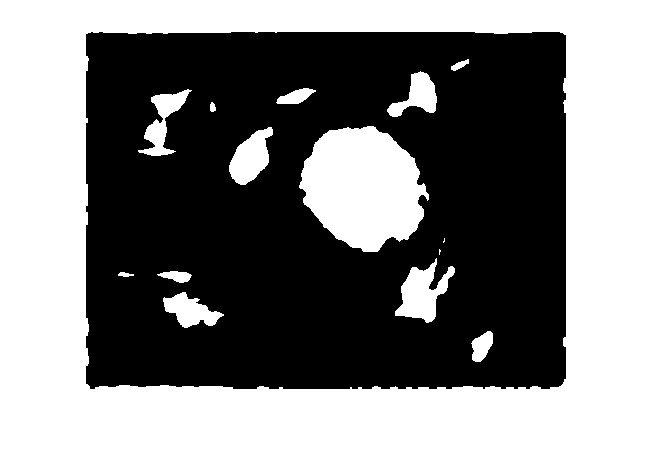

tissue_pot_binary = imcomplement(tissue_pot_binary);
tissue_pot_binary = imfill(tissue_pot_binary,'holes');
imshow(tissue_pot_binary);

Delecting the largest segment and making a boundary

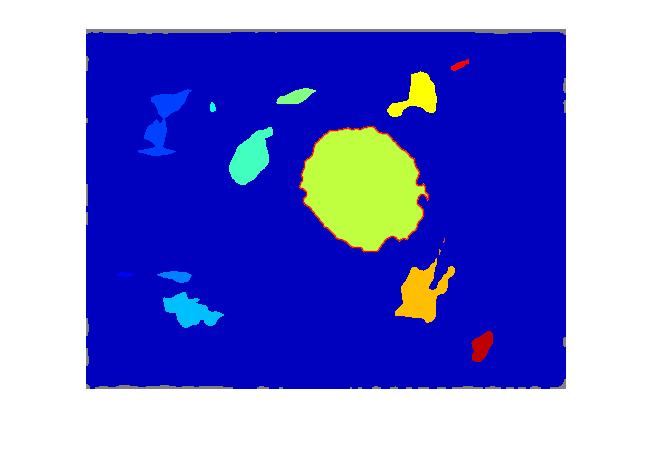

a_bw = imcomplement(tissue_pot_binary);
[B,L] = bwboundaries(a_bw);
imshow(label2rgb(L, @jet, [.5 .5 .5]))
%imshow(a_bw);
hold on
max_size = 0;
max_index = 0;
for k = 1:length(B)
    temp_size = size(B{k},1);
    if temp_size > max_size & temp_size <1000
        max_index = k;
        max_size = temp_size;
    end
end
boundary = B{max_index};
plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 1)

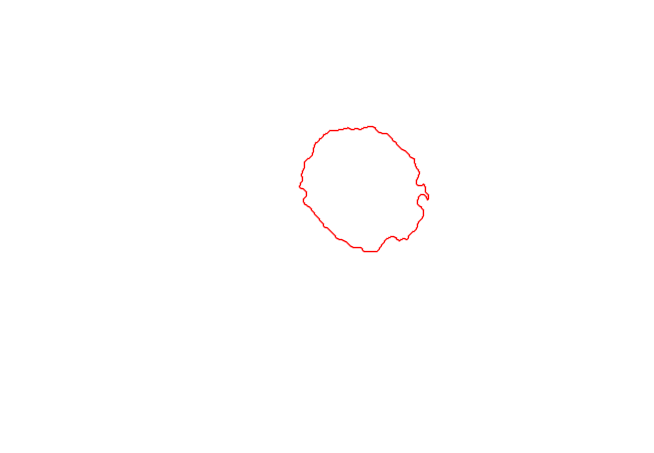

white = ones(360,480);
imshow(white);
hold on
plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 1)

Fill the boundary and remove the other objects

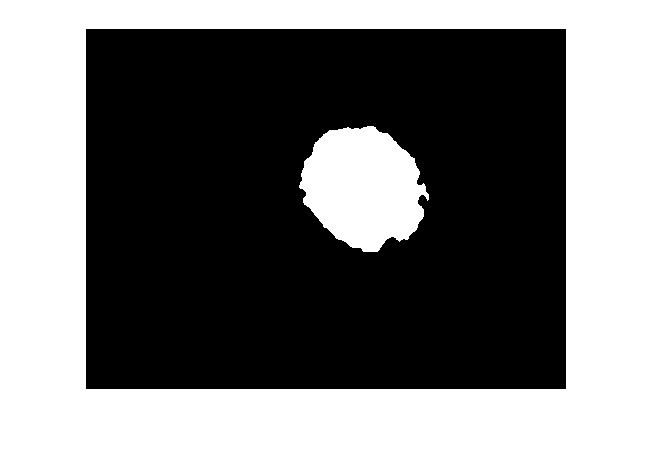

white = zeros(360,480);
I = sub2ind([360,480],boundary(:,1),boundary(:,2));
white(I) = 1;
white = imfill(white,'holes');
imshow(white);